# MERDRONE MK 0.5

clear;
clc;
close all;

Time simulation parameters

t_stop = 3;
t_sample = 1;
tot_frame = (t_stop/t_sample) + t_sample;

Specify some drone parameters

drone.n = 2; %number of drones

Specify lidar sensor parameters

% All followings are [m]
lidar.detection_range = 15;
lidar.range_res = 0.01;
lidar.vertical_fov = 0.1;
lidar.vertical_res = 0.1;
lidar.horizontal_fov = 360;
lidar.horizontal_res = 1;

Loading  enviroment procedure

load_system('env');
load_system('sim_space');
add_block('env/enviroment_1', 'sim_space/enviroment_1', 'MakeNameUnique', 'on');
%open_system('sim_space');

Cyclic insertion of elements that define the working sigle drone

for i=1:drone.n
    ix = 10 * rand;
    iy = 10 * rand;
    iz = rand;
    
    %% ------ Compute the subsystem ------ %%

    add_block('built-in/Subsystem', ['sim_space/vehicle_' num2str(i)]);

    %% ------ Add the drone body and its specs ------ %

    add_block('uavsim3dlib/Simulation 3D UAV Vehicle', ['sim_space/vehicle_' num2str(i) '/drone_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/drone_' num2str(i)''], 'ActorName')
    set_param(['sim_space/vehicle_' num2str(i) '/drone_' num2str(i)''], 'ActorName', ['drone_' num2str(i)''])
    %get_param(['sim_space/vehicle_' num2str(i) '/drone_' num2str(i)''], 'Color')
    set_param(['sim_space/vehicle_' num2str(i) '/drone_' num2str(i)''], 'Color', random_color())
    %get_param(['sim_space/vehicle_' num2str(i) '/drone_' num2str(i)''], 'InitialTranslation')
    vectinit = num2str([ix,iy,iz]) 
    set_param(['sim_space/vehicle_' num2str(i) '/drone_' num2str(i)''], 'InitialTranslation', ['[' vectinit ']'])
    
    %% ------ Add the lidar sensor ------ %

    add_block('uavsim3dlib/Simulation 3D Lidar', ['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'vehTag')
    set_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'vehTag', ['drone_' num2str(i)''])
    %get_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'DistanceOutportEnabled')
    set_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'DistanceOutportEnabled', 'on')
    %get_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'TransformOutportEnabled')
    set_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'TransformOutportEnabled', 'on')
    
    % Add lidar specs

    %get_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'DetectionRange')
    set_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'DetectionRange', num2str(lidar.detection_range))
    %get_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'RangeResolution')
    set_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'RangeResolution', num2str(lidar.range_res))
    %get_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'VerticalFOV')
    set_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'VerticalFOV', num2str(lidar.vertical_fov))
    %get_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'VerticalResolution')
    set_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'VerticalResolution', num2str(lidar.vertical_res))
    %get_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'HorizontalFOV')
    set_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'HorizontalFOV', num2str(lidar.horizontal_fov))
    %get_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'HorizontalResolution')
    set_param(['sim_space/vehicle_' num2str(i) '/Lidar_' num2str(i)''], 'HorizontalResolution', num2str(lidar.horizontal_res))
    
    %% ------ Add to workspace box ------ %%
    
    % Absolute traslation
    add_block('simulink/Sinks/To Workspace', ['sim_space/vehicle_' num2str(i) '/abs_trasl_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/abs_trasl_' num2str(i)''], 'VariableName')
    set_param(['sim_space/vehicle_' num2str(i) '/abs_trasl_' num2str(i)''], 'VariableName',  ['abs_trasl_' num2str(i)''])
    %get_param(['sim_space/vehicle_' num2str(i) '/abs_trasl_' num2str(i)''], 'SaveFormat')
    set_param(['sim_space/vehicle_' num2str(i) '/abs_trasl_' num2str(i)''], 'SaveFormat', 'Structure')
    %get_param(['sim_space/vehicle_' num2str(i) '/abs_trasl_' num2str(i)''], 'Save2DSignal')
    set_param(['sim_space/vehicle_' num2str(i) '/abs_trasl_' num2str(i)''], 'Save2DSignal', '2-D array (concatenate along first dimension)')
    
    % Relative distance of the points
    add_block('simulink/Sinks/To Workspace', ['sim_space/vehicle_' num2str(i) '/rel_dist_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/rel_dist_' num2str(i)''], 'VariableName')
    set_param(['sim_space/vehicle_' num2str(i) '/rel_dist_' num2str(i)''], 'VariableName',  ['rel_dist_' num2str(i)''])
    %get_param(['sim_space/vehicle_' num2str(i) '/rel_dist_' num2str(i)''], 'SaveFormat')
    set_param(['sim_space/vehicle_' num2str(i) '/rel_dist_' num2str(i)''], 'SaveFormat', 'Structure')
    %get_param(['sim_space/vehicle_' num2str(i) '/rel_dist_' num2str(i)''], 'Save2DSignal')
    set_param(['sim_space/vehicle_' num2str(i) '/rel_dist_' num2str(i)''], 'Save2DSignal', '2-D array (concatenate along first dimension)')
   
    % Relative traslation 
    add_block('simulink/Sinks/To Workspace', ['sim_space/vehicle_' num2str(i) '/rel_trasl_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/rel_trasl_' num2str(i)''], 'VariableName')
    set_param(['sim_space/vehicle_' num2str(i) '/rel_trasl_' num2str(i)''], 'VariableName',  ['rel_trasl_' num2str(i)''])
    %get_param(['sim_space/vehicle_' num2str(i) '/rel_trasl_' num2str(i)''], 'SaveFormat')
    set_param(['sim_space/vehicle_' num2str(i) '/rel_trasl_' num2str(i)''], 'SaveFormat', 'Structure')
    %get_param(['sim_space/vehicle_' num2str(i) '/rel_trasl_' num2str(i)''], 'Save2DSignal')
    set_param(['sim_space/vehicle_' num2str(i) '/rel_trasl_' num2str(i)''], 'Save2DSignal', '2-D array (concatenate along first dimension)')
    
    %% ------ Add the simulink point cloud visualization function ------ %% 
    
    add_block('visual_function_block/visual_function', ['sim_space/vehicle_' num2str(i) '/visualabs_trasl_' num2str(i)''], 'MakeNameUnique', 'on');

    %% ------ Add the input comand of the drone ------ %% 
    
    % Add the x value
    add_block('simulink/Sources/Ramp', ['sim_space/vehicle_' num2str(i) '/xramp_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/xramp_' num2str(i)''], 'InitialOutput')
    set_param(['sim_space/vehicle_' num2str(i) '/xramp_' num2str(i)''], 'InitialOutput', num2str(ix))
    %get_param(['sim_space/vehicle_' num2str(i) '/xramp_' num2str(i)''], 'Slope')
    set_param(['sim_space/vehicle_' num2str(i) '/xramp_' num2str(i)''], 'Slope', '5')
    
    % Add the y value
    add_block('simulink/Commonly Used Blocks/Constant', ['sim_space/vehicle_' num2str(i) '/yconst_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/yconst_' num2str(i)''], 'Value')
    set_param(['sim_space/vehicle_' num2str(i) '/yconst_' num2str(i)''], 'Value', num2str(iy))
    
    % Add the z value
    add_block('simulink/Commonly Used Blocks/Constant', ['sim_space/vehicle_' num2str(i) '/zconst_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/zconst_' num2str(i)''], 'Value')
    set_param(['sim_space/vehicle_' num2str(i) '/zconst_' num2str(i)''], 'Value', num2str(iz))
    
    % Add the rotation values
    add_block('simulink/Commonly Used Blocks/Constant', ['sim_space/vehicle_' num2str(i) '/rot_val_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/rot_val_' num2str(i)''], 'Value')
    set_param(['sim_space/vehicle_' num2str(i) '/rot_val_' num2str(i)''], 'Value', '[0, 0, 0]')

    % Add the MUX bus
    add_block('simulink/Commonly Used Blocks/Mux', ['sim_space/vehicle_' num2str(i) '/mux_pilot_' num2str(i)''], 'MakeNameUnique', 'on');
    %get_param(['sim_space/vehicle_' num2str(i) '/mux_pilot_' num2str(i)''], 'Inputs')
    set_param(['sim_space/vehicle_' num2str(i) '/mux_pilot_' num2str(i)''], 'Inputs', '3')
    
    
    
    %% ------ Compute the links ------ %%
    
    % Lidar connections
    add_line(['sim_space/vehicle_' num2str(i)],['Lidar_' num2str(i) '/1'],['visualabs_trasl_' num2str(i) '/1'],'autorouting','on')
    add_line(['sim_space/vehicle_' num2str(i)],['visualabs_trasl_' num2str(i) '/1'], ['rel_trasl_' num2str(i) '/1'],'autorouting','on')
    add_line(['sim_space/vehicle_' num2str(i)],['Lidar_' num2str(i) '/2'],['rel_dist_' num2str(i) '/1'],'autorouting','on')
    add_line(['sim_space/vehicle_' num2str(i)],['Lidar_' num2str(i) '/3'],['abs_trasl_' num2str(i) '/1'],'autorouting','on')
    
    % Inputs connections
    add_line(['sim_space/vehicle_' num2str(i)],['xramp_' num2str(i) '/1'],['mux_pilot_' num2str(i) '/1'],'autorouting','on')
    add_line(['sim_space/vehicle_' num2str(i)],['yconst_' num2str(i) '/1'],['mux_pilot_' num2str(i) '/2'],'autorouting','on')
    add_line(['sim_space/vehicle_' num2str(i)],['zconst_' num2str(i) '/1'],['mux_pilot_' num2str(i) '/3'],'autorouting','on')
    add_line(['sim_space/vehicle_' num2str(i)],['mux_pilot_' num2str(i) '/1'],['drone_' num2str(i) '/1'],'autorouting','on')
    add_line(['sim_space/vehicle_' num2str(i)],['rot_val_' num2str(i) '/1'],['drone_' num2str(i) '/2'],'autorouting','on')
    
    

    %% ------ Reorder the blocks and links ------ %%

    Simulink.BlockDiagram.arrangeSystem(['sim_space/vehicle_' num2str(i)])

end

vectinit = '6.7874      7.5774     0.74313'

vectinit = '6.5548      1.7119     0.70605'

Reorder all the blocks and links in the simulink space

Simulink.BlockDiagram.arrangeSystem('sim_space')

Run the simulation

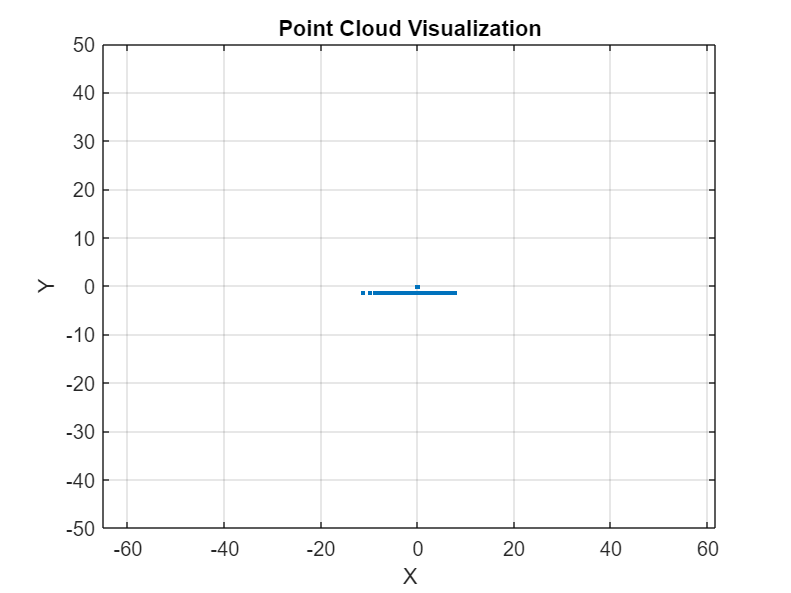

open("sim_space.slx");
set_param('sim_space', 'StopTime', num2str(t_stop));
simulation = sim("sim_space.slx");

Print the lidarscan relative points

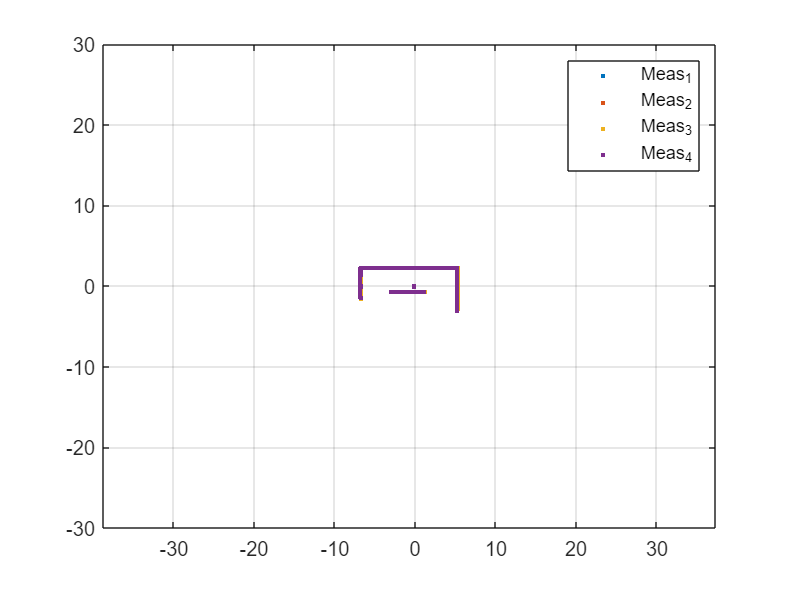

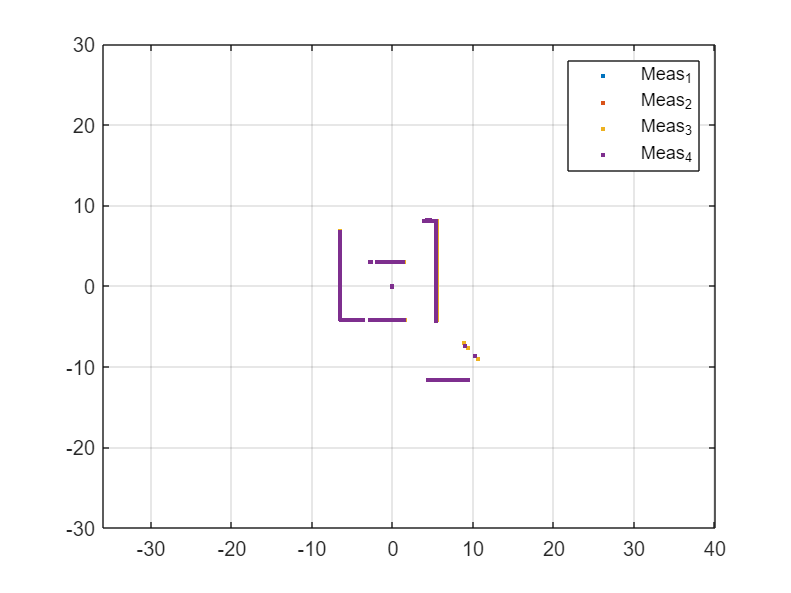

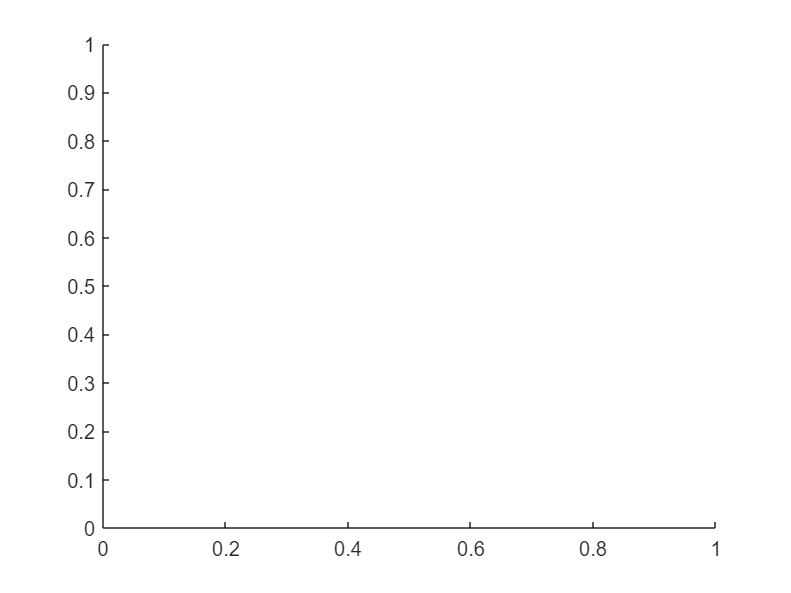

for j=1:drone.n

    field_name_rel_points = ['rel_trasl_' num2str(j)];

    data_trasl = simulation.(field_name_rel_points).signals.values;
    
    
    for i=1:tot_frame
        time = ['time_' num2str(i)];
        struct_data.x.(time) = data_trasl(1, :, 1, i);
        struct_data.y.(time) = data_trasl(1, :, 2, i);
        plot(struct_data.x.(time), struct_data.y.(time), '.');
        hold on;
        legend_entries{i} = sprintf('Meas_%d', i);
    end
    
    grid on;
    xlim([-30, 30]);
    ylim([-30, 30]);
    axis equal;
    legend(legend_entries);
    figure();
    hold off;
end

Save the point distances 

for j=1:drone.n
    field_name_dist_points = ['rel_dist_' num2str(j)];
    data_dist = simulation.(field_name_dist_points).signals.values;
    
    for i=1:tot_frame
        time = ['time_' num2str(i)];
        struct_data.dist.(time) = data_dist(i, :, 1);
    end
end

Plot abs position (Ground truth)

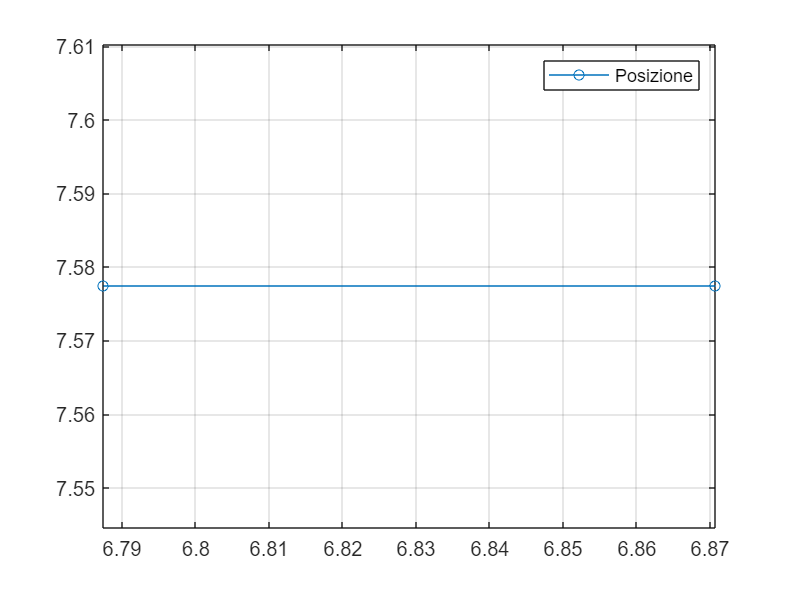

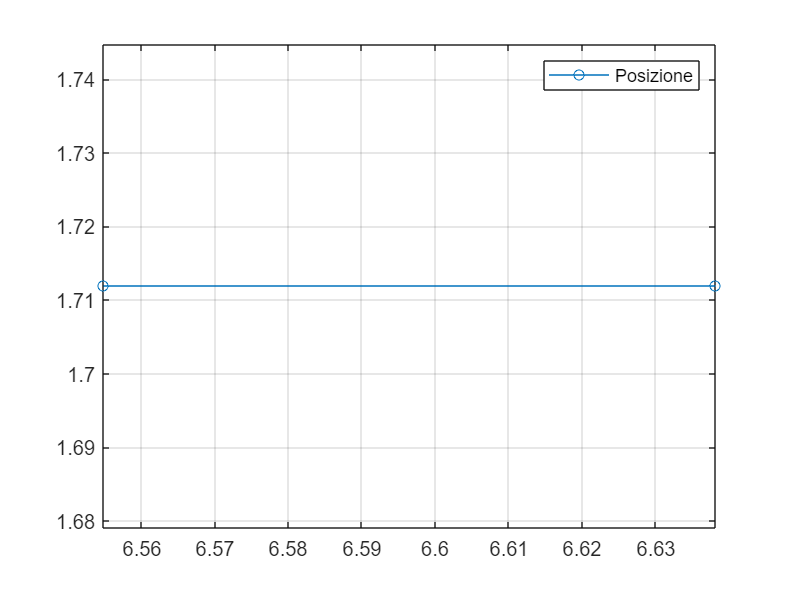

for j=1:drone.n
    field_name_abs_trasl = ['abs_trasl_' num2str(j)];
    data_abs_trasl = simulation.(field_name_abs_trasl).signals.values;
    
    for i=1:tot_frame
        time = ['time_' num2str(i)];
        struct_data.abs_x.(time) = data_abs_trasl(i, 1);
        struct_data.abs_y.(time) = data_abs_trasl(i, 2);
        % struct_data.abs_z.(time) = data_abs_trasl(i, 3);
        x_pos_abs(i) = struct_data.abs_x.(time);
        y_pos_abs(i) =struct_data.abs_y.(time);
    end
    
    plot(x_pos_abs, y_pos_abs, '-o', 'MarkerSize', 5);
    grid on;
    axis equal;
    legend('Posizione');
    figure();
end

AGGIUNGERE SEZIONE DI DELETE DEI BLOCCHI VEICOLI E AMBIENTE